# Kolokwium zaliczeniowe

### Imię i nazwisko:

### Grupa zajęciowa:

# Część I. Analiza wizualizacji danych (10 punktów)

- Dokonaj analizy poniższego wykresu pod względem wizualnego sposobu przekazu. Wypisz wady (i ewentualnie zalety) przedstawionej wizualizacji danych na tym wykresie. 

- Zaporponuj inny (lepszy) sposób (nie wystarczy podać typu wykresu!), aby można było łatwo odczytać i analizować dane.

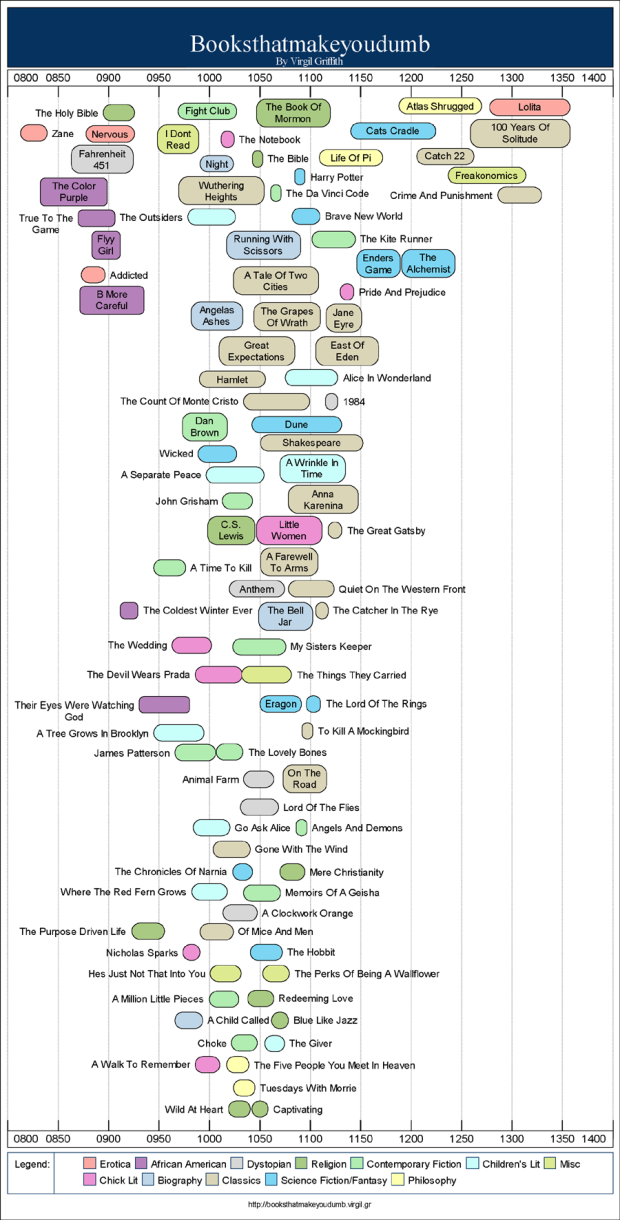

-  tytuł bez spacji, nie wiadomo co określa skala, skala nie od zera, kolorki niekontrastowe, cięzko odróżnić po wielkości kółka która ksiązka bardziej ogłupia

- zaproponowąłbym wykres słupkowy w celu możiwości łatwego porówania która książka bardziej ugłupia 

# Część II. Matlab (20 punktów)

Zadanie 1. (5 punktów)

Dana jest macierz:

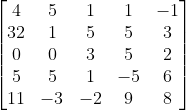

Wyznacz:

a) wartość najmniejszą w każdym wierszu, kolumnie, przekątnej oraz całej macierzy. (3 pkt)

b) macierz transponowaną (1 pkt)

c) sumę wszystkich elementów macierzy (1 pkt)

%takie jak w grupie A

Zadanie 2.

Mając dane examgrades.mat (15 punktów)

a) wyznacz średnie wartości ocen z poszczgólnych przedmiotów (2 pkt)

b) wyznacz odchylenia standardowe poszczególnych ocen z przedmiotów (2 pkt)

c) narysuj wykres typu errorbar. Pamiętaj o przedstawieniu wszystkich elementów związanych z wizualizacją wykresu. (11 pkt)

close all
clear
load examgrades.mat
save examgrades.mat grades -mat
disp('a) wyznacz średnie wartości ocen z poszczgólnych przedmiotów')
srednia = mean(grades)

a) wyznacz średnie wartości ocen z poszczgólnych przedmiotów


disp('wyznacz odchylenia standardowe poszczególnych ocen z przedmiotów')

srednia =    75.0083   74.9917   74.9917   75.0333   74.9917


odchylenie = std(grades)

wyznacz odchylenia standardowe poszczególnych ocen z przedmiotów


przedmioty = categorical(["matematyka" "informatyka" "geoegrafia" "historia" "religia"]);

odchylenie =     8.7202    6.5420    7.4309    8.6013    5.2588


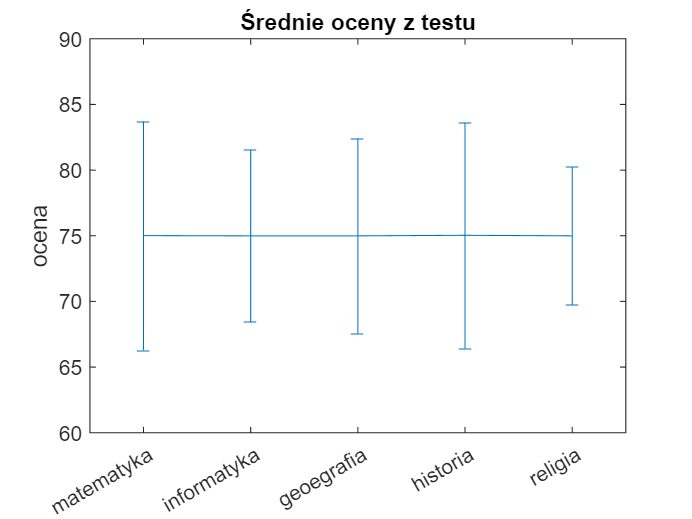

przedmioty=reordercats(przedmioty,["matematyka" "informatyka" "geoegrafia" "historia" "religia"]);

errorbar(przedmioty, srednia, odchylenie)
ylim([60,90])
ylabel("ocena")
title('Średnie oceny z testu')
